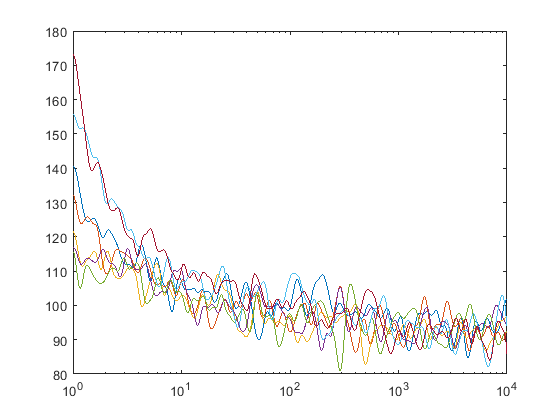

fs = P(1).fs;
for i = 1:length(P)
    gcfr = P(i).avg_gcfr;
    [~,startPt] = max(gcfr);
    stopPt = startPt + 4*fs;
    tonicGCFR(i,:) = P(i).avg_gcfr(startPt : stopPt);
end

t=logspace(0,4, 4*fs+1);
figure;
semilogx(t,tonicGCFR);

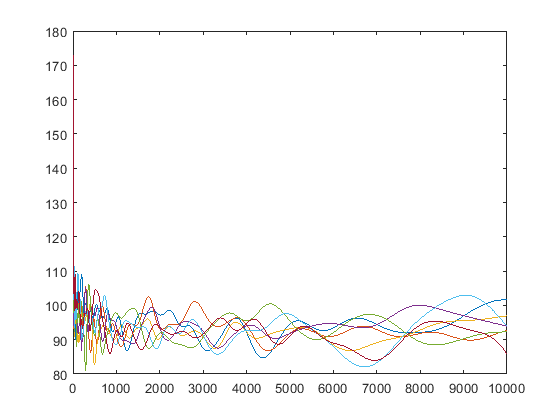


figure;
t1 = linspace(0,4,4*fs+1);
figure;
plot(t,tonicGCFR);